### Tutorial code for exploring an h5 file

#### Define own dataset path and subject to open

DATASET_PATH = 'C:\data\dataset_paper';
SUBJECT = 's14004';

#### Open file and explore its contents

% Construct the full path to the H5 file
h5file = fullfile(DATASET_PATH, 'hdf5_files', [SUBJECT, '.h5']);

% Display the hierarchical structure and data within the file
h5disp(h5file);

HDF5 s14004.h5 
Group '/' 
    Group '/events' 
        Attributes:
            'units':  's'
            'description':  'Events related to the arm movement. Arrays with shape (events, 2) have start_time, end_time. Arrays with shape (events, 1) have single time.'
        Dataset 'extension' 
            Size:  2x20
            MaxSize:  2x20
            Datatype:   H5T_IEEE_F64LE (double)
            ChunkSize:  []
            Filters:  none
            FillValue:  0.000000
        Dataset 'midpoint' 
            Size:  1x20
            MaxSize:  1x20
            Datatype:   H5T_IEEE_F64LE (double)
            ChunkSize:  []
            Filters:  none
            FillValue:  0.000000
        Dataset 'palm_down' 
            Size:  2x1
            MaxSize:  2x1
            Datatype:   H5T_IEEE_F64LE (double)
            ChunkSize:  []
            Filters:  none
            FillValue:  0.000000
        Dataset 'palm_up' 
            Size:  2x1
            MaxSize:  2x1
            Datat

#### First let's explore the metadata

% Access all attributes iteratively and print key: value
% Get information about the 'metadata' group
metadata_info = h5info(h5file, '/metadata');
% Loop through and display each attribute
for i = 1:length(metadata_info.Attributes)
    % Get the current attribute
    attr = metadata_info.Attributes(i);
    % Display its name and value
    fprintf('%s: %s\n', attr.Name, string(attr.Value));
end

age: 21
dominant_side: Right
gender: F
height_cm: 157
weight_kg: 49
primary_activity: Volleyball
arm_length_cm: 60.6542
muscle_thickness_mm: 6.3767
expertise_level: intermediate
probe_side: Left


% Directly read the 'height_cm' attribute from the 'metadata' group
height = h5readatt(h5file, '/metadata', 'height_cm');
disp('Single key, e.g., height (cm)');

Single key, e.g., height (cm)


disp(height);

   157



#### Plot subject's motion capture (mocap) data

First get marker names as well as other relevant information


marker_names = h5readatt(h5file, '/timeseries/mocap', 'markers');
sampling_rate = h5readatt(h5file, '/timeseries/mocap', 'sr');
units = h5readatt(h5file, '/timeseries/mocap', 'units');
description = h5readatt(h5file, '/timeseries/mocap', 'description');

fprintf('Marker names: %s\n', strjoin(marker_names, ', '));

Marker names: hand, forearm, elbow, upperarm, shoulder


fprintf('Sampling rate [Hz]: %f\n', sampling_rate);

Sampling rate [Hz]: 240.000000


fprintf('Units: %s\n', units);

Units: cm


fprintf('Description: %s\n', description);

Description: Optitrack motion capture data for arm markers. The array is a 3D array with shape (samples, markers, coordinates).


Retrieve data from h5file and plot the first 4 arm markers

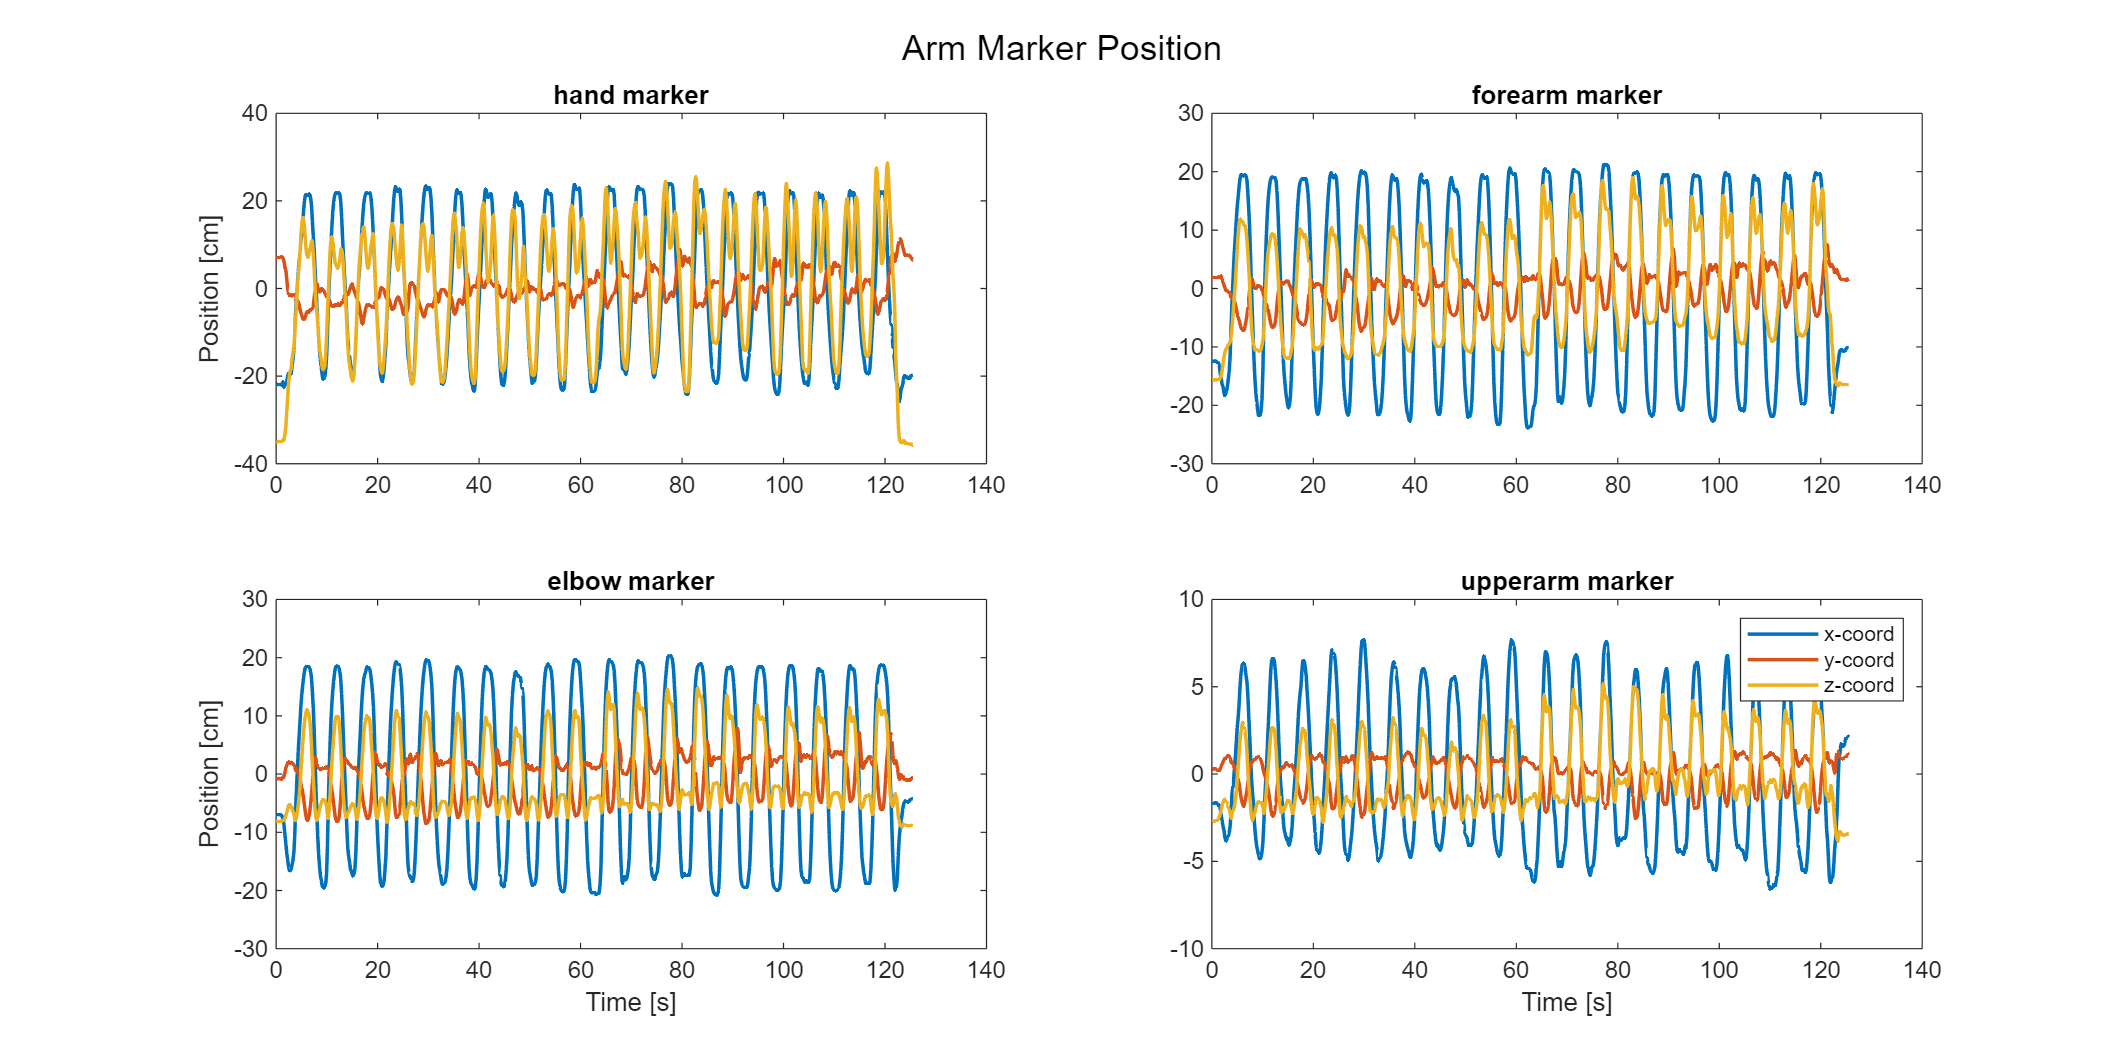

% Read the time vector, mocap data, and marker names attribute
time = h5read(h5file, '/timeseries/mocap/time');
mocap_arrays = h5read(h5file, '/timeseries/mocap/data');
marker_names = h5readatt(h5file, '/timeseries/mocap', 'markers');

figure('Position', [100, 100, 1200, 600]); % Create a figure window of a size big enough

% Loop through each marker except the last one
for idx = 1:length(marker_names) - 1
    ax = subplot(2, 2, idx);
    data_for_marker = squeeze(mocap_arrays(:, idx, :));
    % Center the data for visualization purposes
    data_plot = data_for_marker - mean(data_for_marker, 2);
    
    plot(ax, time, data_plot, 'LineWidth', 1.5);
    
    title(ax, sprintf('%s marker', marker_names{idx}));
    
    if mod(idx, 2) ~= 0
        ylabel(ax, 'Position [cm]');
    end
    if idx > 2 
        xlabel(ax, 'Time [s]');
    end
end

legend(ax, 'x-coord', 'y-coord', 'z-coord');
sgtitle('Arm Marker Position');

#### Plot subject's arm speed with extension/retraction intervals

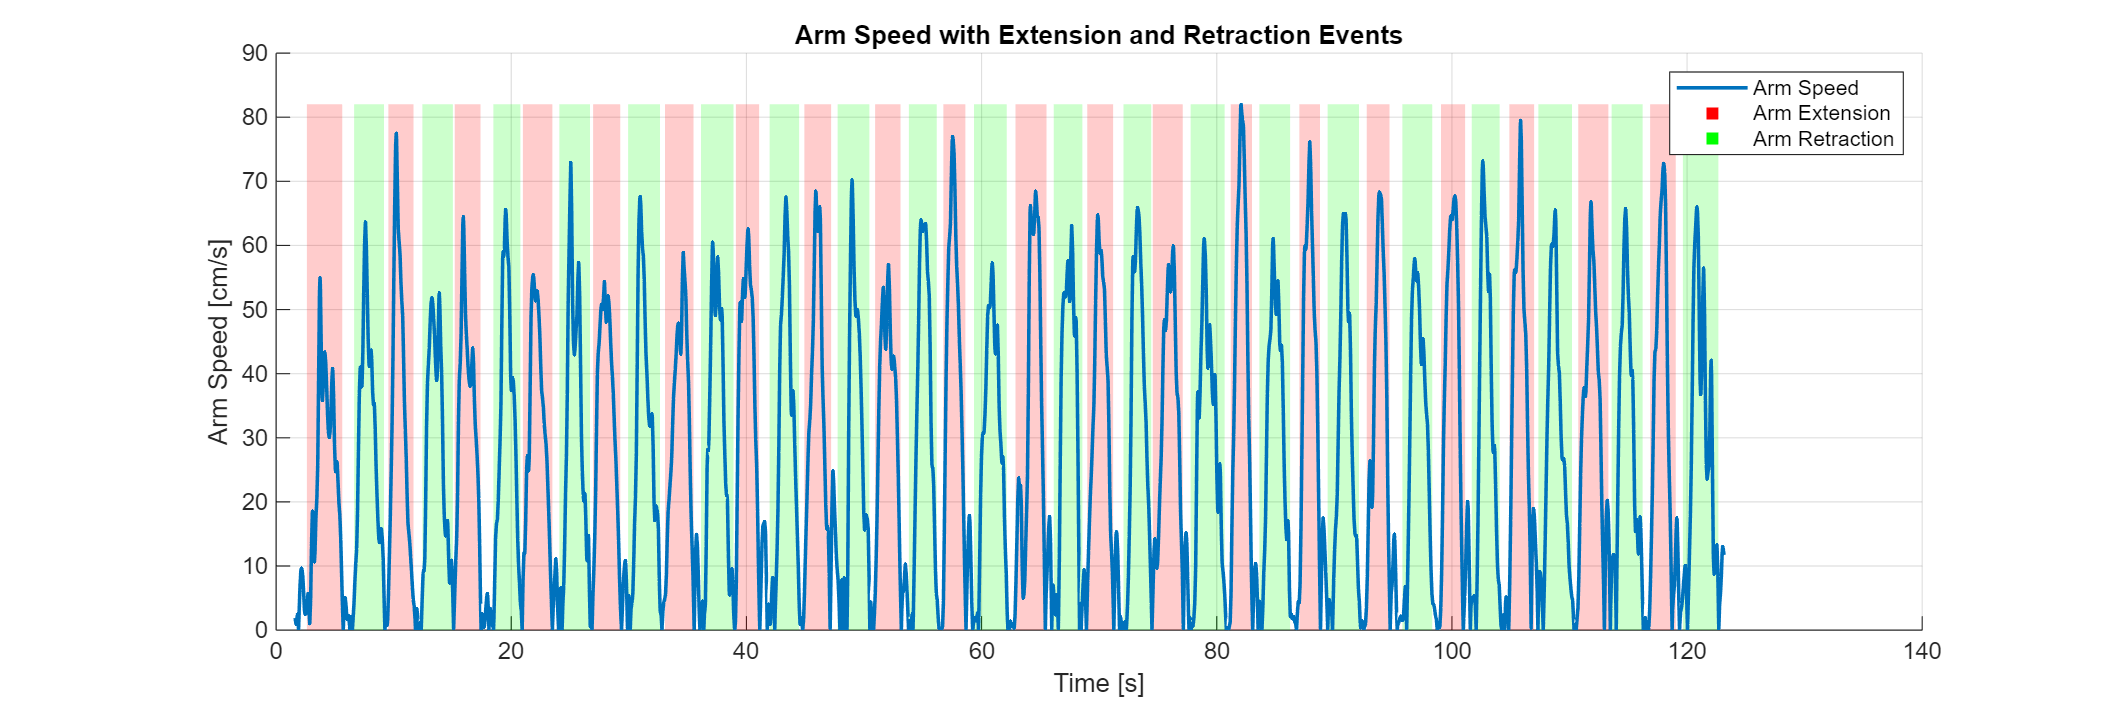

% Retrieve and plot arm speed with events
arm_time = h5read(h5file, '/timeseries/arm_speed/time');
arm_data = h5read(h5file, '/timeseries/arm_speed/data');
units = h5readatt(h5file, '/timeseries/arm_speed', 'units');

extension = h5read(h5file, '/events/extension');
retraction = h5read(h5file, '/events/retraction');

figure('Position', [100, 100, 1200, 400]); % Create a wide figure
hold on;

% Set labels and title
xlabel('Time [s]');
ylabel(sprintf('Arm Speed [%s]', units));
title('Arm Speed with Extension and Retraction Events');

% Get the y-axis limits for the shaded regions
min_v = min(arm_data);
max_v = max(arm_data);
y_limits = [min_v, max_v];

% Plot extension shaded areas
for i = 1:size(extension, 2)
    start_time = extension(1, i);
    end_time = extension(2, i);
    patch([start_time, end_time, end_time, start_time], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], ...
          'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
end

% Plot retraction shaded areas
for i = 1:size(retraction, 2)
    start_time = retraction(1, i);
    end_time = retraction(2, i);
    patch([start_time, end_time, end_time, start_time], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], ...
          'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
end

% Plot the main speed data over the shaded regions
plot(arm_time, arm_data, 'LineWidth', 1.5, 'DisplayName', 'Arm Speed');
legend();

% To create a clean legend, we can plot invisible "dummy" lines that will
% serve as the legend entries for our shaded regions.
plot(NaN, NaN, 's', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r', 'DisplayName', 'Arm Extension');
plot(NaN, NaN, 's', 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'g', 'DisplayName', 'Arm Retraction');
grid on;
hold off;

#### Plot subject's acceleration and tremor power on the triceps with tremor events

% Retrieve and plot acceleration and tremor signals
acc_time = h5read(h5file, '/timeseries/acc/time');
acc_data = h5read(h5file, '/timeseries/acc/data');
locations = h5readatt(h5file, '/timeseries/acc', 'locations');

tp_time = h5read(h5file, '/timeseries/tremor_power/time');
tp_data = h5read(h5file, '/timeseries/tremor_power/data');

events = h5read(h5file, '/events/tremor_triceps');

% Confirm that 'triceps' is the first location
fprintf('Sensor locations: %s\n', strjoin(locations, ', '));

Sensor locations: triceps, biceps, palm


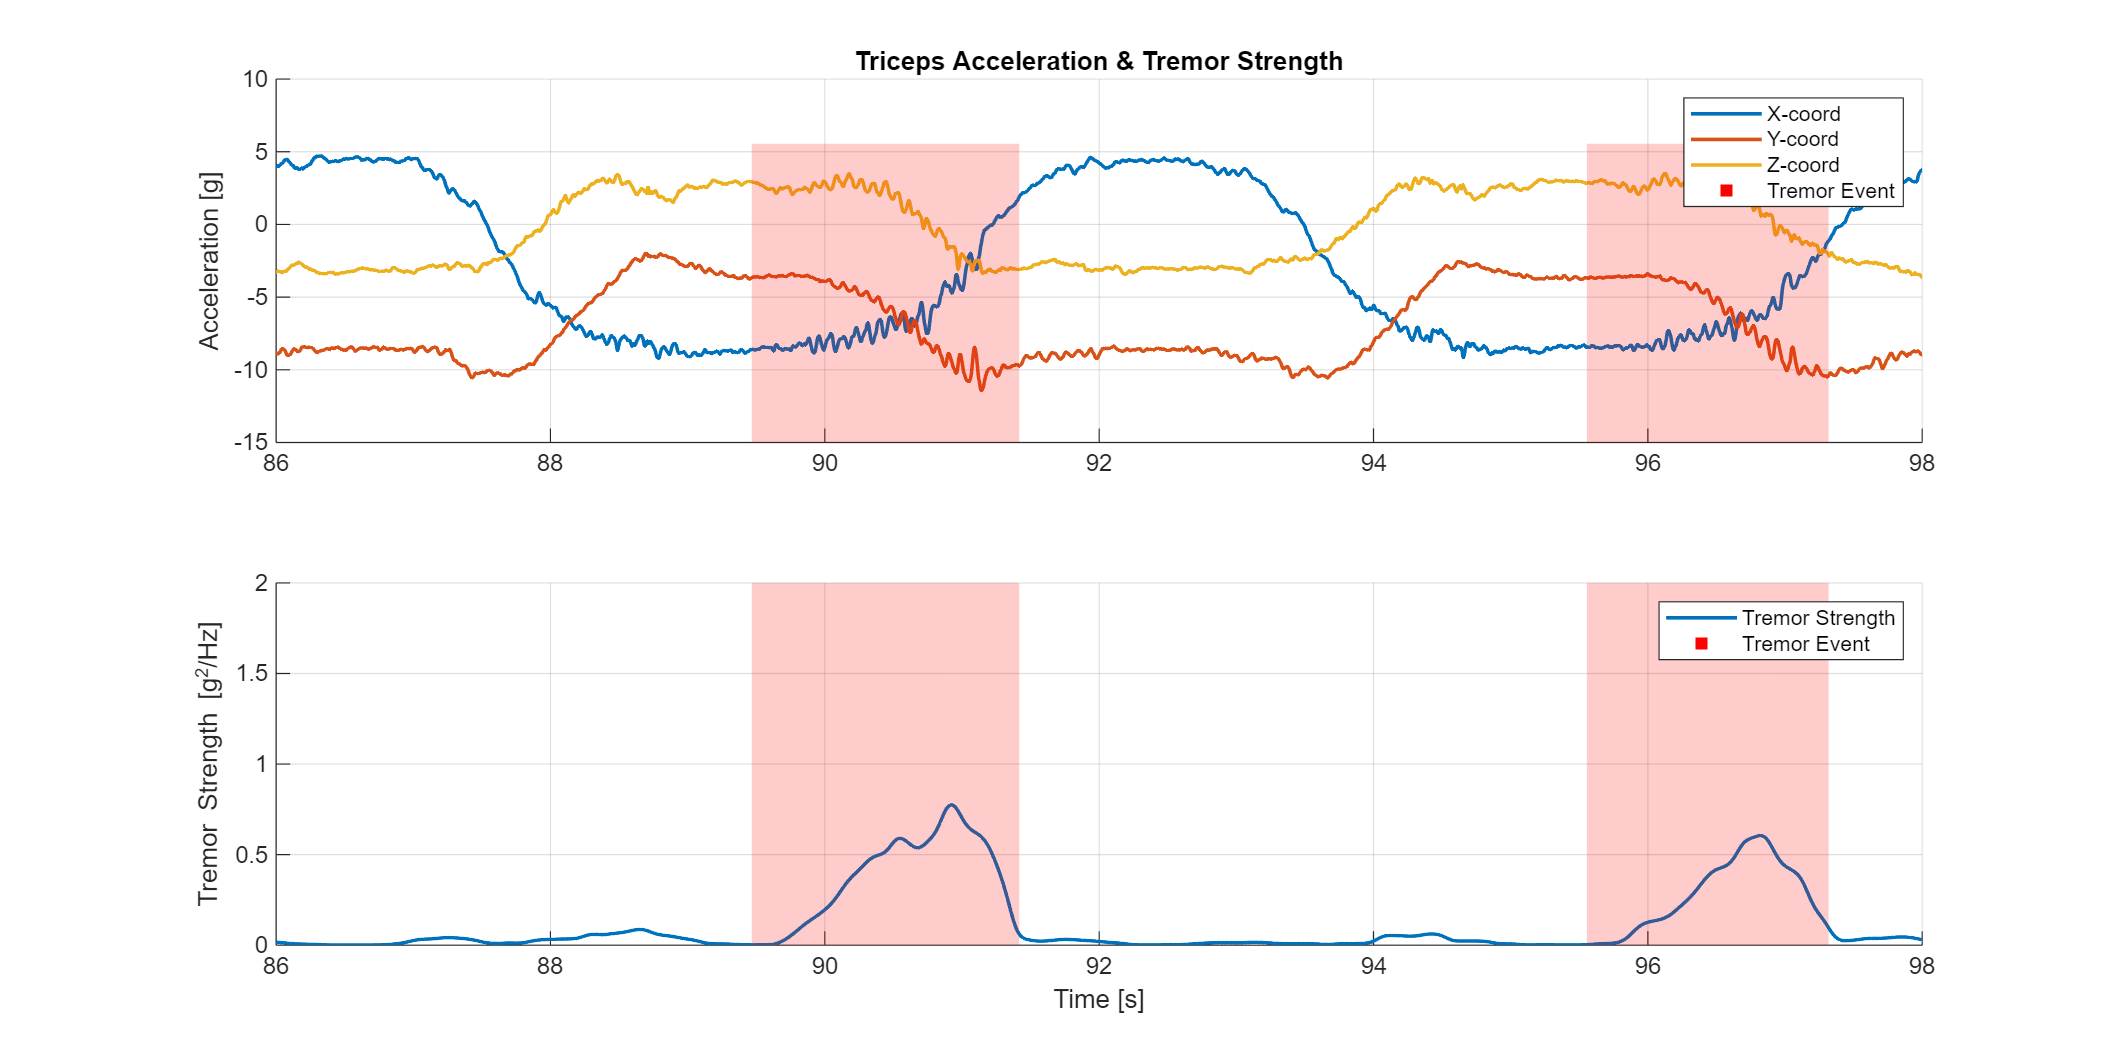

triceps_idx = 1;

figure('Position', [100, 100, 1200, 600]);

ax1 = subplot(2, 1, 1);
hold(ax1, 'on');

ax2 = subplot(2, 1, 2);
hold(ax2, 'on');
triceps_acc_data = squeeze(acc_data(:, triceps_idx, :));
plot(ax1, acc_time, triceps_acc_data(1,:), 'DisplayName', 'X-coord', 'LineWidth', 1.5);
plot(ax1, acc_time, triceps_acc_data(2,:), 'DisplayName', 'Y-coord', 'LineWidth', 1.5);
plot(ax1, acc_time, triceps_acc_data(3,:), 'DisplayName', 'Z-coord', 'LineWidth', 1.5);

plot(ax2, tp_time, tp_data(triceps_idx,:), 'DisplayName', 'Tremor Strength', 'LineWidth', 1.5);


y_limits_ax1 = ylim(ax1); 
y_limits_ax2 = ylim(ax2);
for i = 1:size(events, 2)
    start_time = events(1, i);
    end_time = events(2, i);
    
    % Draw patch on the top subplot (ax1)
    patch(ax1, [start_time, end_time, end_time, start_time], [y_limits_ax1(1), y_limits_ax1(1), y_limits_ax1(2), y_limits_ax1(2)], ...
          'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
          
    % Draw patch on the bottom subplot (ax2)
    patch(ax2, [start_time, end_time, end_time, start_time], [y_limits_ax2(1), y_limits_ax2(1), y_limits_ax2(2), y_limits_ax2(2)], ...
          'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
end

% --- Add Labels, Titles, and Legends ---
% Add a dummy plot for a clean legend entry
plot(ax1, NaN, NaN, 's', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r', 'DisplayName', 'Tremor Event');

title(ax1, 'Triceps Acceleration & Tremor Strength');
ylabel(ax1, 'Acceleration [g]');
legend(ax1, 'Location', 'northeast');
grid(ax1, 'on');
hold(ax1, 'off');

% Add a dummy plot for the second legend
plot(ax2, NaN, NaN, 's', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r', 'DisplayName', 'Tremor Event');

xlabel(ax2, 'Time [s]');
ylabel(ax2, 'Tremor Strength [g^2/Hz]');
legend(ax2, 'Location', 'northeast');
grid(ax2, 'on');
hold(ax2, 'off');

% Link the x-axes of the two subplots
linkaxes([ax1, ax2], 'x');
% Set some x range to appreciate the tremors (comment this out to see the whole trace)
xlim([86, 98]);

#### Plot subject's EMG

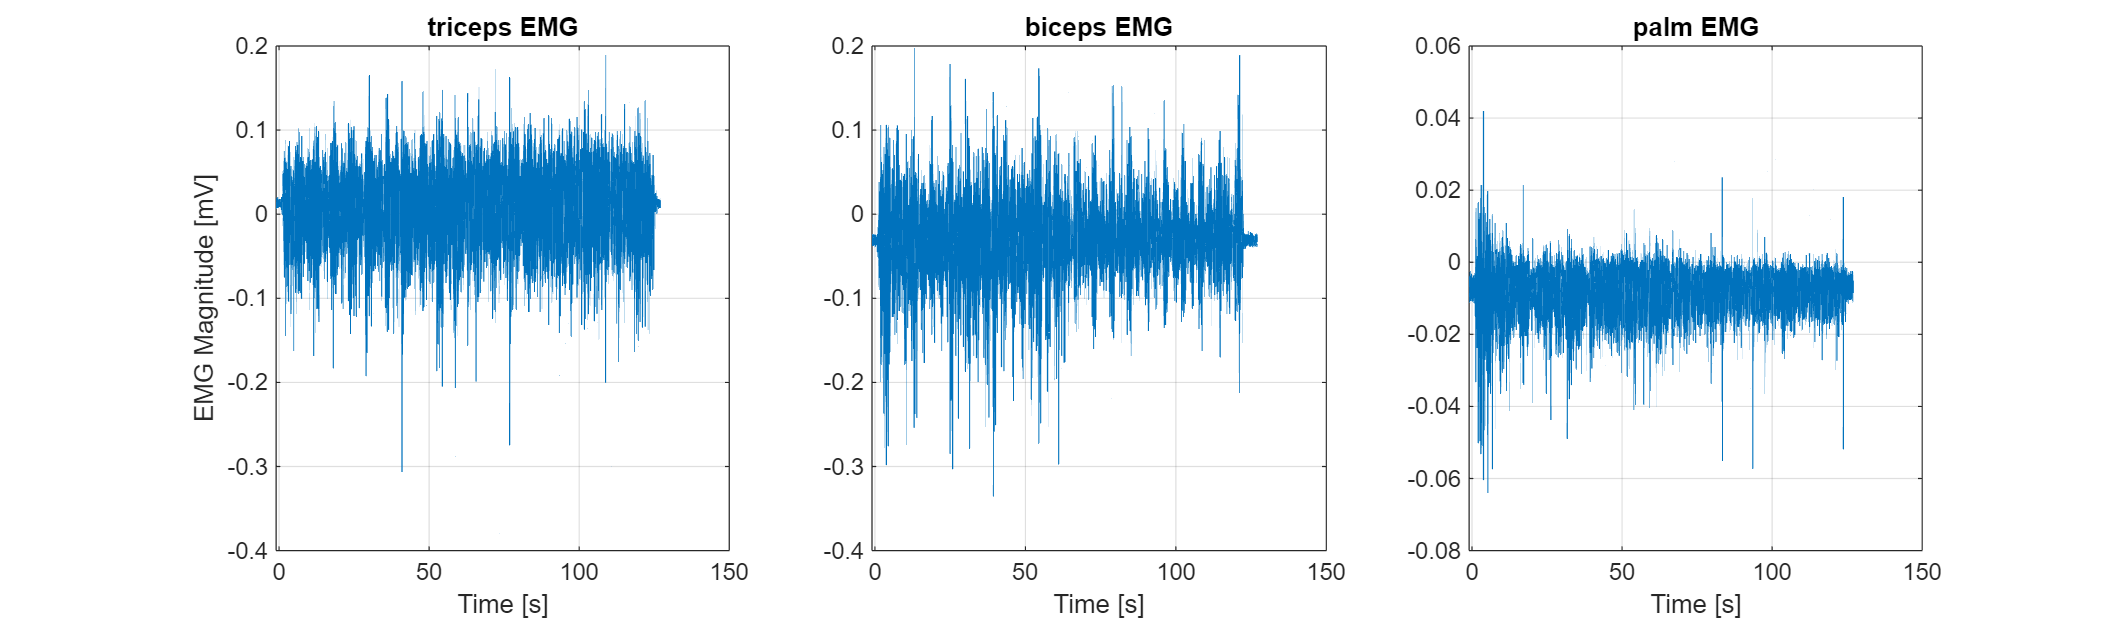

% Retrieve and plot EMG signals
time = h5read(h5file, '/timeseries/emg/time');
emg_data = h5read(h5file, '/timeseries/emg/data');

locations = h5readatt(h5file, '/timeseries/emg', 'locations');
units = h5readatt(h5file, '/timeseries/emg', 'units');

figure('Position', [100, 100, 1200, 350]); % Create a wide figure

for idx = 1:length(locations)
    ax = subplot(1, 3, idx);
    plot(ax, time, emg_data(idx, :));
    title(ax, sprintf('%s EMG', locations{idx}));
    xlabel(ax, 'Time [s]');

    if idx == 1
        ylabel(ax, sprintf('EMG Magnitude [%s]', units));
    end
    
    grid on;
end

#### Plot and overlay tracked trajectories on the ultrasound video and play it

Explore all the attributes

% Get information about the '/timeseries/us_trackers' group
us_info = h5info(h5file, '/timeseries/us_trackers');

% Loop through and display each attribute
for i = 1:length(us_info.Attributes)
    % Get the current attribute
    attr = us_info.Attributes(i);

    if ischar(attr.Value)
        fprintf('%s: %s\n', attr.Name, string(attr.Value));
    elseif isnumeric(attr.Value)
        fprintf('%s: %g\n', attr.Name, attr.Value);
    else
        fprintf('%s: %s\n', attr.Name, strjoin(attr.Value, ', '));
    end
end

video_name: s14004.mp4


sr: 59.976


tracker_names: br0, br1, br2, br3, tr0, tr1, tr2, tr3, fascia, fasciabone, sidebone
coordinates: x, y


units: mm
probe_placement: Left


pixel_size_mm: 0.0756048
probe_width_mm: 37.5
depth_mm: 49.6
shape: 656
ǰ: 

description: Ultrasound tracker data for arm movement. The array is a 3D array with shape (frames, trackers, coordinates).


Retrieve and plot 4 tracker trajectories

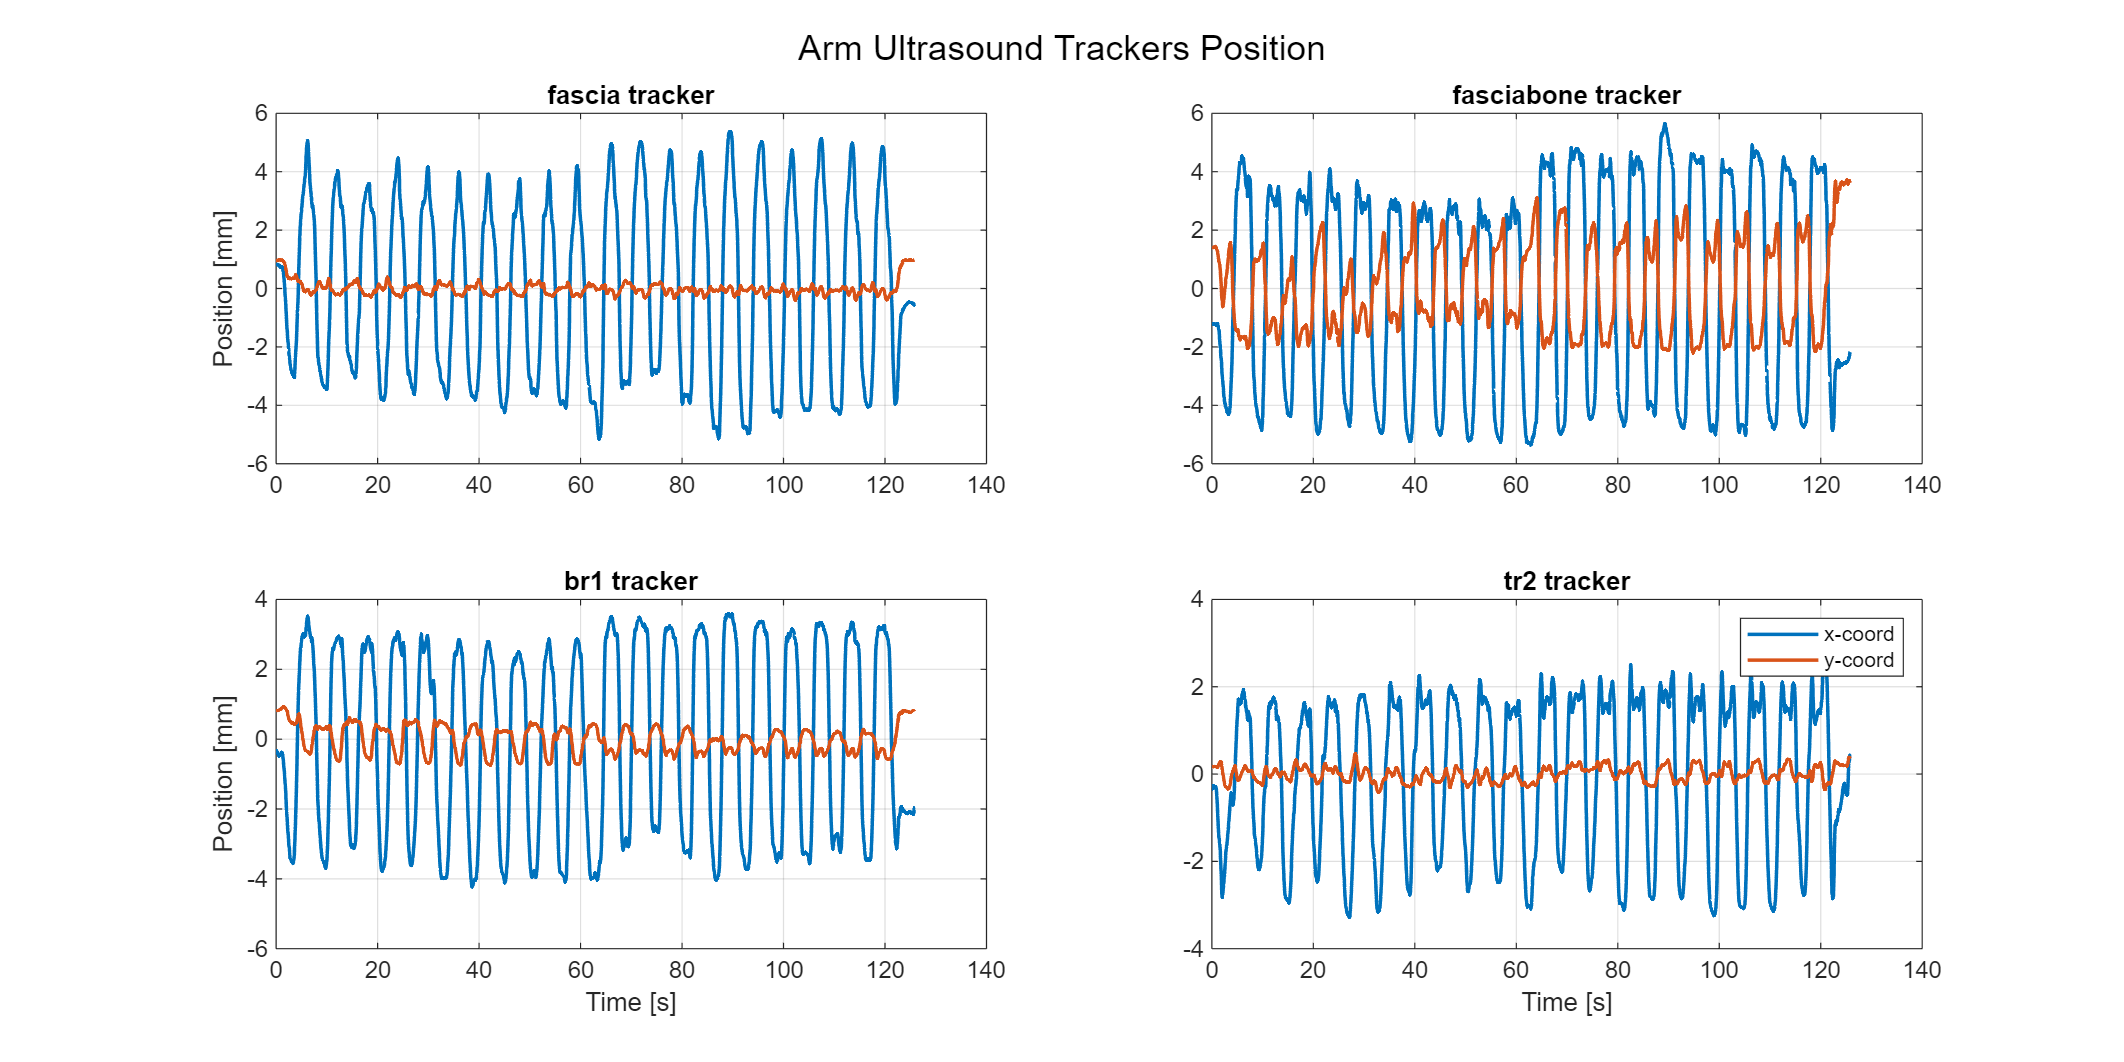

us_time = h5read(h5file, '/timeseries/us_trackers/time');
us_arrays = h5read(h5file, '/timeseries/us_trackers/data');

% Define the labels for the trackers
labels = {'fascia', 'fasciabone', 'br1', 'tr2'};
all_labels = h5readatt(h5file, '/timeseries/us_trackers', 'tracker_names');

figure('Position', [100, 100, 1200, 600]);

for idx = 1:length(labels)
    ax = subplot(2, 2, idx);
    current_tracker = labels{idx};
    jdx = find(strcmp(all_labels, current_tracker));
    data_for_tracker = squeeze(us_arrays(:, jdx, :));
    
    % Center the data for visualization purposes
    data_plot = data_for_tracker - mean(data_for_tracker, 2);
    
    plot(ax, us_time, data_plot, 'LineWidth', 1.5);
    title(ax, sprintf('%s tracker', labels{idx}));
    
    if mod(idx, 2) ~= 0
        ylabel(ax, 'Position [mm]');
    end
    if idx > 2
        xlabel(ax, 'Time [s]');
    end
    grid(ax, 'on');
end

legend(ax, 'x-coord', 'y-coord');
sgtitle('Arm Ultrasound Trackers Position');

Overlay trajectories to the video and play it

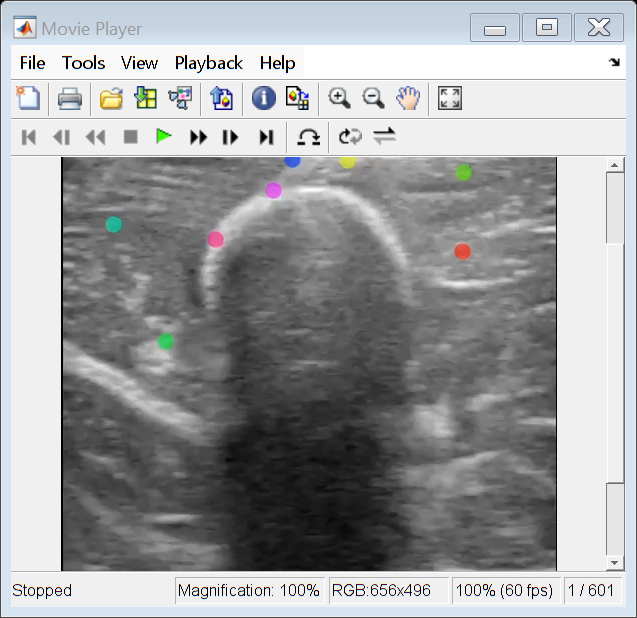

% Define frames to process and the output path
start_frame = 100;
end_frame = 700;
save_path = fullfile(DATASET_PATH, 'us_videos', 'processed_video.mp4');

% Read necessary data and attributes from the H5 file
video_name = h5readatt(h5file, '/timeseries/us_trackers', 'video_name');
pixel_size_mm = h5readatt(h5file, '/timeseries/us_trackers', 'pixel_size_mm');
us_arrays = h5read(h5file, '/timeseries/us_trackers/data');

video_path = fullfile(DATASET_PATH, 'us_videos', video_name);
videoReader = VideoReader(video_path);
video_chunk = read(videoReader, [start_frame, end_frame]);
tracker_chunk = us_arrays(:, :, start_frame:end_frame) / pixel_size_mm;

cmap = hsv(size(tracker_chunk, 2)); 
colors = cmap * 255;

videoWriter = VideoWriter(save_path, 'MPEG-4');
videoWriter.FrameRate = videoReader.FrameRate;
open(videoWriter);

for i = 1:size(video_chunk, 4)
    frame = video_chunk(:,:,:,i);
    markers = tracker_chunk(:, :, i)';

    valid_indices = ~any(isnan(markers), 2);
    valid_markers = markers(valid_indices, :);
    valid_colors = colors(valid_indices, :);
    
    if ~isempty(valid_markers)
        circle_positions = [valid_markers, ones(size(valid_markers, 1), 1) * 8];
        frame = insertShape(frame, 'FilledCircle', circle_positions, 'Color', valid_colors);
    end
    
    writeVideo(videoWriter, frame);
end

close(videoWriter);

implay(save_path);